# Демодуляция. Часть 2.

# Double Sideband Suppressed Carrier 

# (AM-DSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Когерентная демодуляция с помощью возведения сигнала в квадрат

Для качественного приема АМ-сигналов когерентным способом необходимо точное совпадение частоты и фазы несущей и генератора в приемнике. Чтобы этого добиться для сигнала с подавленной несущей, нужно использовать специальную систему фазовой автоподстройки частоты, которая выполняется возведение принимаемого сигнала в квадрат. Схема приемного устройства будет иметь вид:

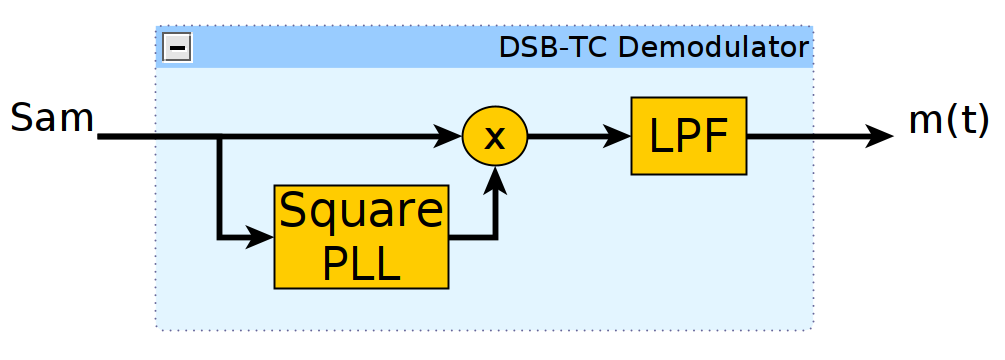

В отличие от классической PLL, которая состоит из фазового детектора, петлевого фильтра и управляемого генератора, в данной PLL присутствует еще несколько узлов. Схема представлена ниже: 

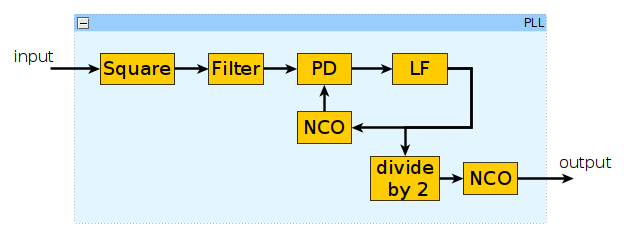

Блок Square выполняет возведение сигнала в квадват. Далее результат фильтруется блоком Filter и подается на фазовый детектор обычной PLL. Внутри схемы присутствует дополнительный управляемый генератор, на вход которого подается уменьшенный вдвое сигнал от петлевого фильтра. Выход этого генератора является выходом PLL.

Чтобы лучше понять принцип работы схемы, представим выполняемые преобразования в аналитическом виде. Пусть принятый АМ-сигнал имеет вид:

$s_{\textrm{am}} \left(t\right)=m\left(t\right)\cdot \cos \left(2\pi f_c t\right)$,

где $m\left(t\right)$ - информационное сообщение, $f_c$ - частота несущей. Также пусть не выполняется условие $m\left(t\right)\ge 0$, то есть сообщение изменяет знак. Как было показано в DSB SC Receiver Part 1, если подать такой сигнал на вход обчной PLL, то восстановленный сигнал будет искажен. Причину искажения можно объяснить следующим образом. PLL плавно подстраивает фазу управляемого генератора, чтобы она совпадала с фазой несущей. Изменение знака информационного сообщения равносильно скачкообразному изменению фазы несущей на 180 градусов. Это приводит к рассогласованию и новой подстройки управляемого генератора. Чем чаще сообщение $m\left(t\right)$ изменяет знак, тем чаще появляются скачки, и тем чаще выполняется пересинхронизация. Это все отрицательно сказывается на качестве восстановленного сообщения.

Если сделать так, чтобы амплитуда несущей не изменяла знак, то скачки пропадут, и это решит проблему. Для этого принятый АМ-сигнал нужно возвести в квадрат и отфильтровать. После возведения в квадрат и применения формулы произведения косинусов получим:

$s_{\textrm{square}} \left(t\right)=m^2 \left(t\right)\cdot \cos^2 \left(2\pi f_c t\right)=\frac{1}{2}m^2 \left(t\right)+\frac{1}{2}m^2 \left(t\right)\cdot \cos \left(2\pi \cdot 2f_c \cdot t\right)$.

Таким образом, сигнал содержит квадрат сообщения и несущую на удвоенной частоте, амплитуда которой уже не изменяет знак. Квадрат сообщения можно убрать с помощью полосового фильтра или фильтра верхних частота. Выход фильтра будет иметь вид:


$$s_{\textrm{filter}} \left(t\right)=\frac{1}{2}m^2 \left(t\right)\cdot \cos \left(2\pi \cdot 2f_c \cdot t\right)\ldotp$$


Если этот сигнал подать на вход PLL, она подстроит управляемый генератор под удвоенную частоту несущей $2f_c$. Однако, для когерентного приема нужен сигнал, частота которого равна частоте несущей. Для этого используется второй NCO, частота настройки которого уменьшается в два раза, за счет детеления на два сигнала с выхода петлевого фильтра. Таким образом, получается гармонический сигнал, который по частоте и фазе совпадается с несущей.

Для реализации всех рассмотренных выше преобразований был создан Matlab System Object, описание которого находится в файле SquareAmSignalPLL.m. В качестве фильтра внутри PLL используется фильтр верхних частот. Ниже представлен скрипт, выполняющий когерентный прием сигнала с подавленной несущей. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

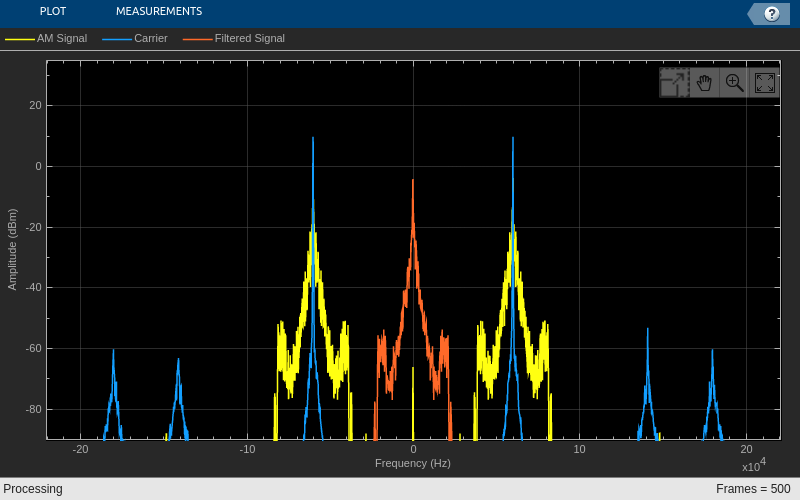

clc; clear; close all;
addpath('matlab/DSB_SC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
% параметры фапч зависят от квадрата амплитуды входного сигнала
% его амплитуда меняется поэтому берем среднее значение, равное 0.0012
AmPLL = SquareAmSignalPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.0012 ...
    );

% рассчет коэффициентов фильтра нижних частот
H = Audio_Lowpass_FIR_Coeff();

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Filtered Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % восстанавливаем несущую
    [Carrier, Offset] = AmPLL(AmSignal);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* Carrier;

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal Carrier BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Синим - спектр восстановденной несущей на выходе PLL. После переноса по частоте и фильтрации остается только информационное сообщение (красный).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что при расстройке в 100 Гц демодулированный сигнал не содержит искажений. При расстройке в 1000 Гц сначала слышны сильные искажения, а потом качество сигнала исправляется. Этот временный эффект соответствует периоду вхождения PLL в режим синхронизации. Из-за большей расстройки по частоте длительность этого процесса увеличивается. При расстройке в 5000 Гц, слышны сильные искажения. Это происходит из-за того, что расстройка по частоте превышает полосу захвата PLL, поэтому PLL не может войти в режим синхронизации.

В файле *DSB_SC_Receiver_Part_2_1.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. В модели присутствует обычная PLL и PLL, выполняющая возведение в квадрат. С помощью переключателя можно выбрать, каккую из низ них использовать и сравнить качество восстановления аудиосообщения.

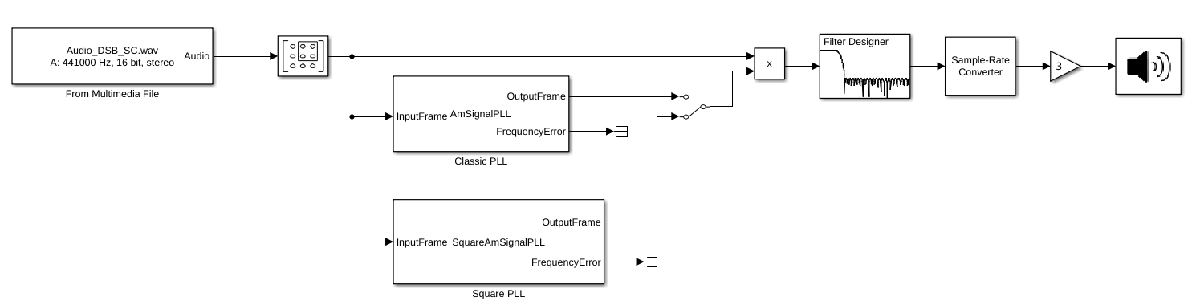

### 2. Когерентная демодуляция с помощью возведения в квадрат при квадратурном приеме

Рассмотрим как изменится структура когерентного демодулятора с возведением в квадрат в случае квадратурного приема. Сигнал теперь комплексный с односторонним спектром и представлен в виде:

 $s_{\textrm{am}} \left(t\right)=m\left(t\right)\cdot e^{j\cdot 2\pi f_c t}$,

где $m\left(t\right)$ - информационное сообщение, $f_c$ - частота несущей. После возведения в квадрат получим:

$s_{\textrm{square}} \left(t\right)=m^2 \left(t\right)\cdot e^{j\cdot 2\pi \cdot 2f_c \cdot t}$.

Таким образом, получаем комплексное гармоническое колебание амплитуда, которого не изменяет знак. Этот сигнал можно уже подавать на вход обычной PLL. То есть, в случае квадатурного приема схема демодулятора будет иметь тот же самый выд, что и для действительного сигнала, за исключением того, что теперь после возведения в квадрат не нужно выполнять фильтрацию.

Для реализации всех рассмотренных выше преобразований был создан Matlab System Object, описание которого находится в файле SquareAmComplexPLL.m. Ниже представлен скрипт, выполняющий когерентный прием сигнала с подавленной несущей. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

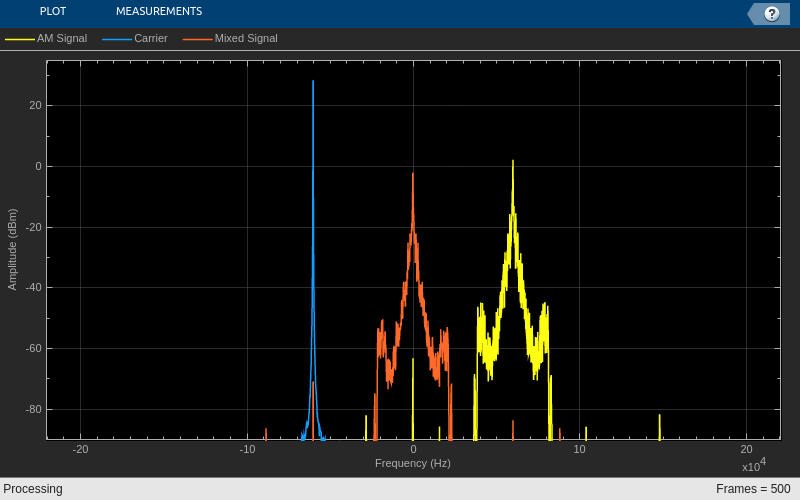

clc; clear; close all;
addpath('matlab/DSB_SC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
AmPLL = SquareAmComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % восстанавливаем несущую
    [Carrier, Offset] = AmPLL(AmSignal);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* conj(Carrier);
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal conj(Carrier) MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

 Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Так как прием квадратурный, спектр сигнала комплексный и расположен только в положительной области частот. Синим цветом представлен сигнал на выходе NCO PLL, а красным - сигнал на выходе смесителя. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

При прослушавании принятого сигнала при разных значениях расстройки по частоте получаем те же самые искажения, что и для действительного случая. При расстройке по частоте в 5000 Гц сигнал на выходе NCO содержит множество гармоник и не является комплексной экспонентой. Это означает, что PLL не находится в режиме синхронизации.

В файле *DSB_SC_Receiver_Part_2_2.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. В модели присутствует обычная PLL и PLL, выполняющая возведение в квадрат. С помощью переключателя можно выбрать, каккую из низ них использовать и сравнить качество восстановления аудиосообщения.

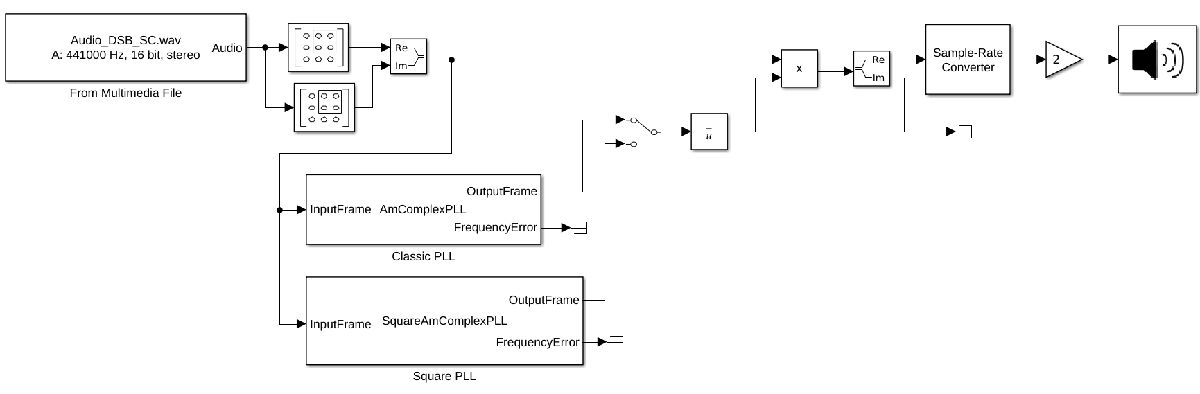

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR

- M. Rice Digital Communications. A Discrete Time Approach

- B. Sclar Digital Communications. Fundamentals and Applications